# Machine Learning with MATLAB

Digital Twin & Automation

# SVM Classification 

## Example1: Circular Distribution

### Dataset 1:  Random Generation for Circular Distribution

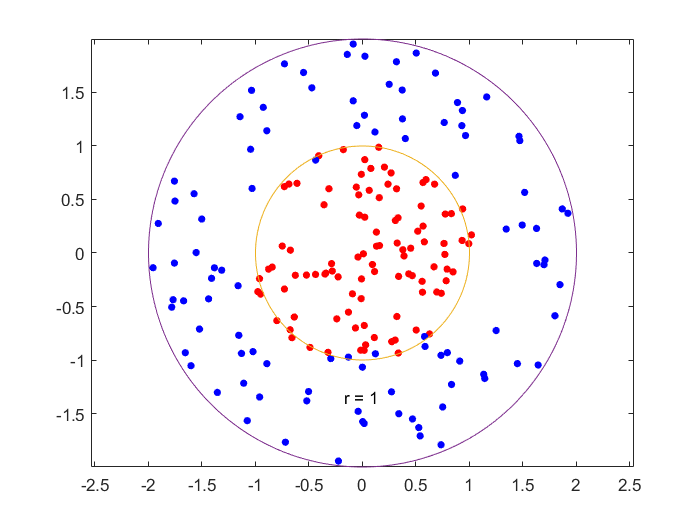

rng(1); % For reproducibility

% Class y=-1
r = sqrt(1.1*rand(100,1)); % Radius
t = 2*pi*rand(100,1);  % Angle
data1 = [r.*cos(t), r.*sin(t)]; % Points
% Class y=1
r2 = sqrt(3*rand(100,1)+0.9); % Radius
t2 = 2*pi*rand(100,1);      % Angle
data2 = [r2.*cos(t2), r2.*sin(t2)]; % points

dataC = [data1;data2];
theclass = ones(200,1);
theclass(1:100) = -1;

figure;
plot(data1(:,1),data1(:,2),'r.','MarkerSize',15)
hold on
plot(data2(:,1),data2(:,2),'b.','MarkerSize',15)
ezpolar(@(x)1);ezpolar(@(x)2);
axis equal
hold off

### Train SVM 

% With Box Constraint =inf
cl = fitcsvm(dataC,theclass,'KernelFunction','rbf',...
    'BoxConstraint',Inf,'ClassNames',[-1,1]);
%애로하면 조금더 정확해짐 이유를 공부 해보자


% With Box Constraint default
% cl = fitcsvm(dataC,theclass,'KernelFunction','rbf');


### **Anlayze (Train Data)**

**Resubstitution error**:  misclassification error  on the training set.

mlResubErr = resubLoss(cl)

mlResubErr = 0

**Confusion matrix** on the training set

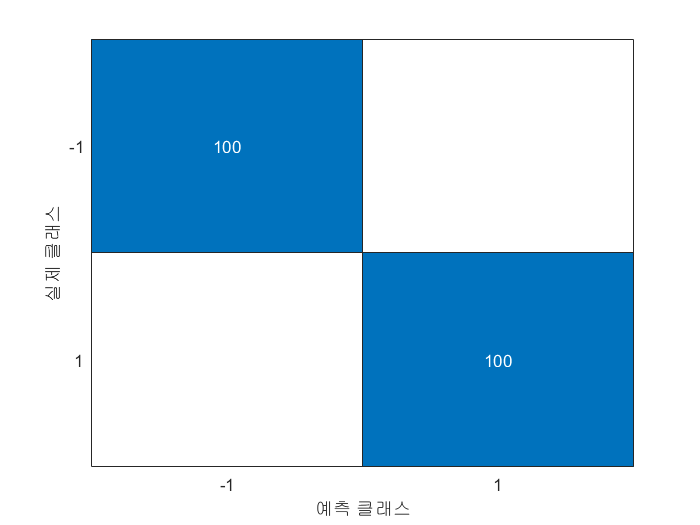

mlClass = resubPredict(cl);

figure
ldaResubCM = confusionchart(theclass,mlClass);

**Predict scores over the grid**

d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(dataC(:,1)):d:max(dataC(:,1)),...
    min(dataC(:,2)):d:max(dataC(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
[~,scores] = predict(cl,xGrid);


**Plot the data and the decision boundary**

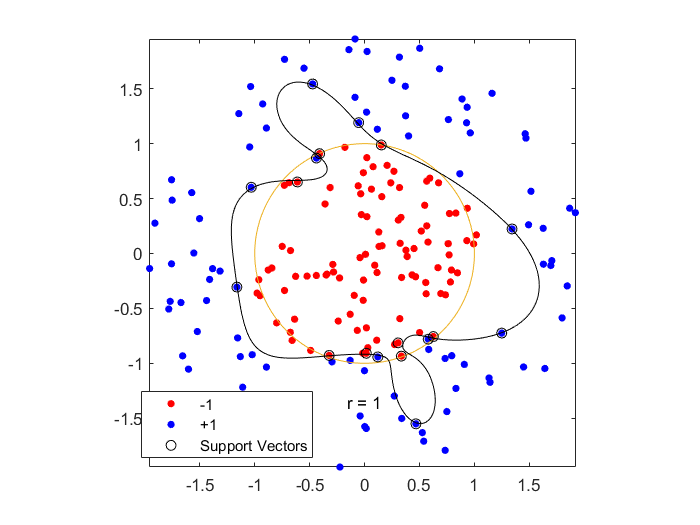

figure;
h(1:2) = gscatter(dataC(:,1),dataC(:,2),theclass,'rb','.');
hold on
ezpolar(@(x)1);
h(3) = plot(dataC(cl.IsSupportVector,1),dataC(cl.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h,{'-1','+1','Support Vectors'});
axis equal
hold off

### **Validation (CV)**

Estimate the true test error for LDA using 10-fold stratified cross-validation.

rng(0)
cp = cvpartition(theclass,'KFold',10)  %k-fold

cp = K-겹 교차 검증 분할
   NumObservations: 200
       NumTestSets: 10
         TrainSize: 180  180  180  180  180  180  180  180  180  180
          TestSize: 20  20  20  20  20  20  20  20  20  20


cvml = crossval(cl,'CVPartition',cp);
mlCVErr = kfoldLoss(cvml)

mlCVErr = 0.0800

# Exercise  

## Exercise 1: SVM Classification with CWRU

### Dataset :  CWRU dataset features

- Given dataset contains many features extracted from CWRU dataset

- We will select 2~3 features for exercise

- For binary class:  Outer and Inner Race Fault

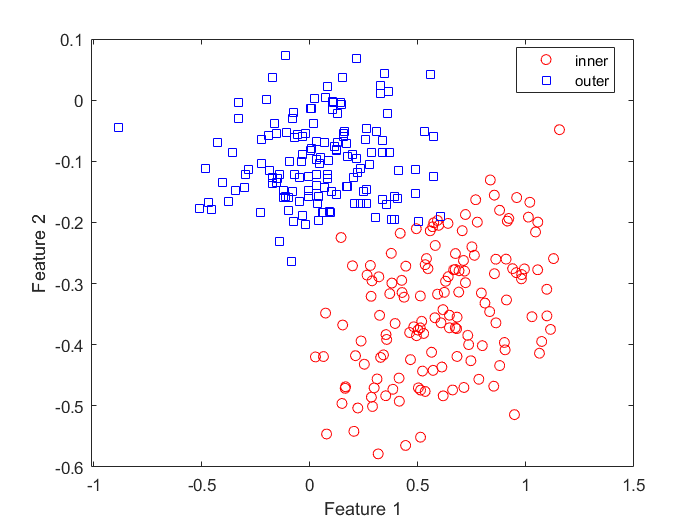

clear

% Eliminate clas 'normal'. Keep 'Inner', 'Outer'
load("../4weeks_machine_learning_1/CWRU_features/example_train.mat");
feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor
Xtrain(:, 1) = table2array(glob_all_train(:, feature1));
Xtrain(:, 2) = table2array(glob_all_train(:, feature2));

Ytrain = class_cwru_train;       % fault class
classKeep = ~strcmp(Ytrain,'normal');
X = Xtrain(classKeep,:);
Y = Ytrain(classKeep);
N = size(X,1);

% Plot
f = figure;
gscatter(X(:,1), X(:,2), Y,'rb','os');
xlabel('Feature 1');
ylabel('Feature 2');

### **CV Partition**

% cvpartition to generate 10 disjoint stratified subsets.

%%% YOUR CODE GOES HERE
cv = cvpartition(Y,'KFold',10)  %k-fold

cv = K-겹 교차 검증 분할
   NumObservations: 288
       NumTestSets: 10
         TrainSize: 260  259  259  259  259  259  259  259  259  260
          TestSize: 28  29  29  29  29  29  29  29  29  28

###  Train SVM 

%%% YOUR CODE GOES HERE
% specifiy class name:  fitcsvm(..., 'ClassNames',{'outer','inner'})
cl =  fitcsvm(X, Y,'ClassNames',{'outer','inner'})

cl =   ClassificationSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'outer'  'inner'}
           ScoreTransform: 'none'
          NumObservations: 288
                    Alpha: [77×1 double]
                     Bias: -2.2185
         KernelParameters: [1×1 struct]
           BoxConstraints: [288×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [288×1 logical]
                   Solver: 'SMO'


  Properties, Methods


### **Anlayze (Train Data)**

**Resubstitution error**:  misclassification error  on the training set.

%%% YOUR CODE GOES HERE
mlResubErr = resubLoss(cl)

mlResubErr = 0.0313

**Confusion matrix** on the training set

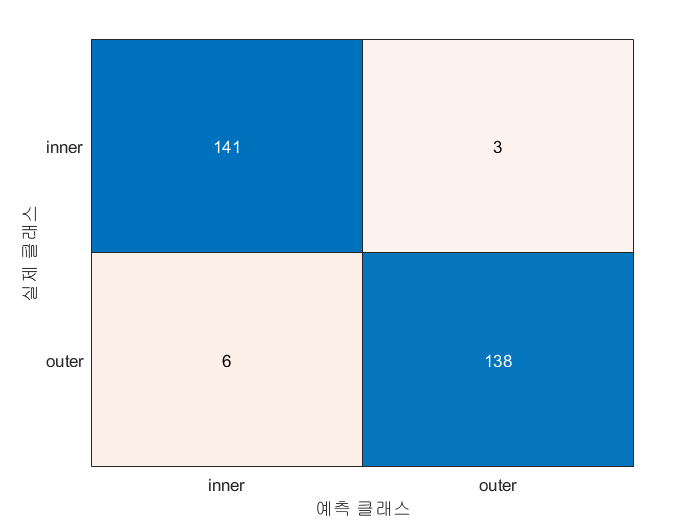

%%% YOUR CODE GOES HERE
mlClass = resubPredict(cl);

figure
ldaResubCM = confusionchart(Y,mlClass);

**Predict scores over the grid**

d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(X(:,1)):d:max(X(:,1)),...
    min(X(:,2)):d:max(X(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];

[~,scores] = predict(cl,xGrid);


**Plot the data and the decision boundary**

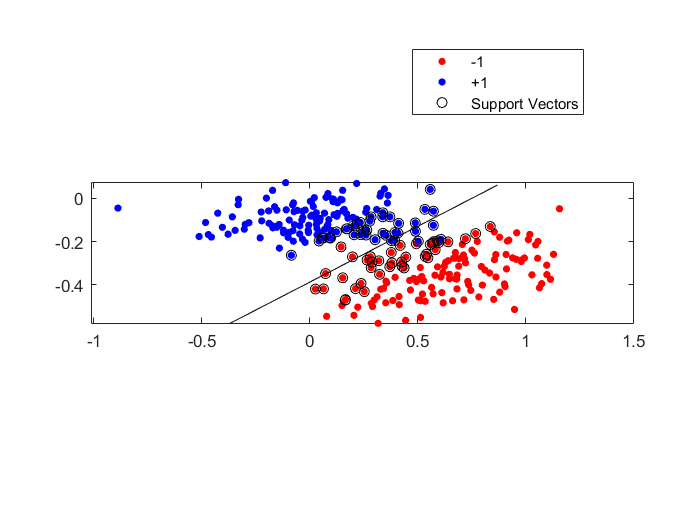

figure;
h(1:2) = gscatter(X(:,1),X(:,2),Y,'rb','.');
hold on
h(3) = plot(X(cl.IsSupportVector,1),X(cl.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h,{'-1','+1','Support Vectors'});
axis equal
hold off

### **Validation (CV)**

Estimate the true test error  using 10-fold stratified cross-validation.

%%% YOUR CODE GOES HERE
rng(0)
cp = cvpartition(Y,'KFold',10)  %k-fold

cp = K-겹 교차 검증 분할
   NumObservations: 288
       NumTestSets: 10
         TrainSize: 260  259  259  259  259  259  259  259  259  260
          TestSize: 28  29  29  29  29  29  29  29  29  28

Cross validate and show cv loss

%%% YOUR CODE GOES HERE
cvml = crossval(cl,'CVPartition',cp);
mlCVErr = kfoldLoss(cvml)

mlCVErr = 0.0313

## Exercise 2: CWRU 

Now, Use all 3 classes:  normal,  outer, inner.  Apply Multi_Class SVM 

**Features**

clear

% Eliminate clas 'normal'. Keep 'Inner', 'Outer'
load("../4weeks_machine_learning_1/CWRU_features/example_train.mat");
feature1 = "kv";                % Kurtosis value of time data
feature2 = "mf";                % marginal factor
feature3 = "cf";                % crest factor
Xtrain(:, 1) = table2array(glob_all_train(:, feature1));
Xtrain(:, 2) = table2array(glob_all_train(:, feature2));
Xtrain(:, 3) = table2array(glob_all_train(:, feature3));

Ytrain = class_cwru_train;       % fault class
%classKeep = ~strcmp(Ytrain,'normal');
%X = Xtrain(classKeep,:);
%Y = Ytrain(classKeep);
X = Xtrain;
Y = Ytrain;
N = size(X,1);

plot 

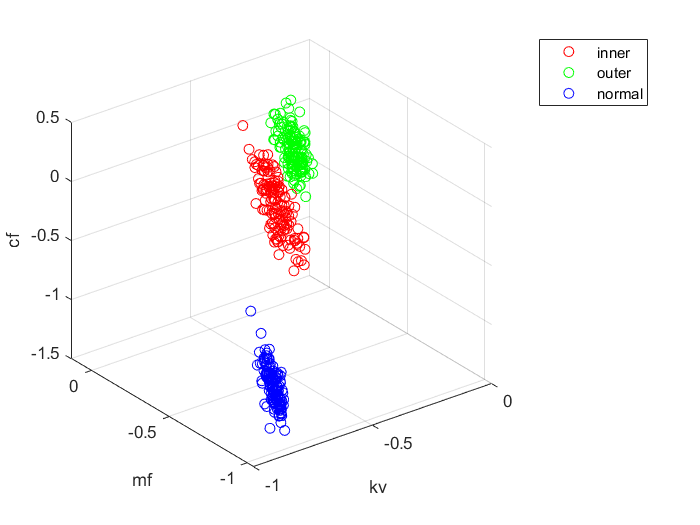

Y_cate = categorical(Y);
idx_inner = Y_cate == 'inner';
idx_outer = Y_cate == 'outer';
idx_normal = Y_cate == 'normal';

figure
plot3(X(idx_inner,1),X(idx_inner,2),X(idx_inner,3),'ro')
hold on
plot3(X(idx_outer,1),X(idx_outer,2),X(idx_outer,3),'go')
plot3(X(idx_normal,1),X(idx_normal,2),X(idx_normal,3),'bo') 
grid on
xlabel('kv')
ylabel('mf')
zlabel('cf')
legend('inner','outer','normal')
hold off

Analyze  the test and train results 

### **CV Partition**

% cvpartition to generate 10 disjoint stratified subsets.

%%% YOUR CODE GOES HERE
cv = cvpartition(Y,'KFold',10)  %k-fold

cv = K-겹 교차 검증 분할
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43

###  Train SVM 

%%% YOUR CODE GOES HERE

t = templateSVM('Standardize',true,'SaveSupportVectors',true);
Mdl = fitcecoc(X,Y,'Learners',t,...
    'ClassNames',{'inner','outer','normal'});
% Your code goes here
CVMdl = crossval(Mdl); 
genError = kfoldLoss(CVMdl)

genError = 0

Mdl.HyperparameterOptimizationResults


ans =

     []



%%% YOUR CODE GOES HERE
mlResubErr = resubLoss(Mdl)

mlResubErr = 0

**Confusion matrix** on the training set

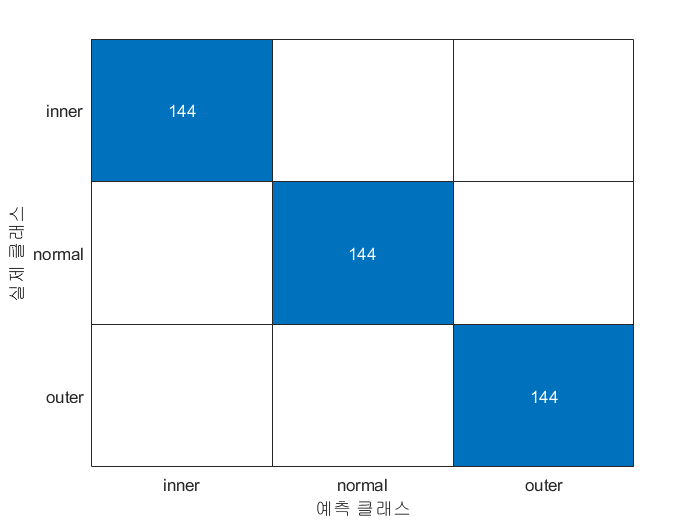

%%% YOUR CODE GOES HERE
mlClass = resubPredict(Mdl);

figure
ldaResubCM = confusionchart(Y,mlClass); 

## Exercise 3 

 Compare performance of SVM with  LDA, QDA, Logistic Regression

**Logistic Regression은 두가지 class(1,0)으로 구분할 때 유용한 방법이다. **CWRU dataset에서** normal class를 제외하여 inner와 outer에 대해 분류를 할때 적합하다. Logistic Regression을 이용할 때의 손실은 약 0.0556이다. **

**LDA와 QDA는 class가 여러개 있어도 분류가 가능하다. class가 3개 이상 있을 때 유용한 방법이라고 할 수 있다. LDA와 QDA의 loss는 0으로 Logistic Regression보다 더 정확하다고 할 수있다.**

**하지만 LDA와 LQA를 선정함에 있어서 LDA는 각각의 class가 normal distribution을 가지고있고 covariance가 같은 것을 전재로 한다. **

**SVM도 LDA/QDA와 마찬가지로 여러 class에 대해 분류가 가능하다. 손실의 측면에서 SVM도 0을 나타내고 있다. 분류의 측면에 있어 두 model 모두 적합하다고 할 수 있다. **

** covariance: 두 독립변수가 상관관계를 가지고 있다. **

**손실**함수는 **머신러닝**의 현재 성능과 목표값(정답값)을 정량화한 값으로, **머신러닝** 학습이란 **손실**함수 최소화를 의미한다.